clc
clear
close all

Import Bags

bag1 = rosbag('/LAB4/data_going_in_circles.bag');
bag2 = rosbag('/LAB4/data_driving.bag');
circlesGPS = readMessages(select(bag1, 'Topic', '/gps'), 'DataFormat', 'struct');
circlesIMU = readMessages(select(bag1, 'Topic', '/imu'), 'DataFormat', 'struct');
drivingGPS = readMessages(select(bag2, 'Topic', '/gps'), 'DataFormat', 'struct');
drivingIMU = readMessages(select(bag2, 'Topic', '/imu'), 'DataFormat', 'struct');
% disp(circlesIMU{1}.Imu)
% disp(drivingGPS{1}.Header)

Extract Data

calX = cellfun(@(m) double(m.MagField.MagneticField_.X), circlesIMU);
calY = cellfun(@(m) double(m.MagField.MagneticField_.Y), circlesIMU);
calZ = cellfun(@(m) double(m.MagField.MagneticField_.Z), circlesIMU);
circlessecs = cellfun(@(m) double(m.Header.Stamp.Sec), circlesIMU);
circlesnsecs = cellfun(@(m) double(m.Header.Stamp.Nsec), circlesIMU);
circlestime = circlessecs + circlesnsecs*10^-9;
circlestime = circlestime(1225:5072); circlestime = circlestime - circlestime(1);

qX = cellfun(@(m) double(m.Imu.Orientation.X), drivingIMU);
qY = cellfun(@(m) double(m.Imu.Orientation.Y), drivingIMU);
qZ = cellfun(@(m) double(m.Imu.Orientation.Z), drivingIMU);
qW = cellfun(@(m) double(m.Imu.Orientation.W), drivingIMU);

driveMagX = cellfun(@(m) double(m.MagField.MagneticField_.X), drivingIMU);
driveMagY = cellfun(@(m) double(m.MagField.MagneticField_.Y), drivingIMU);
driveMagZ = cellfun(@(m) double(m.MagField.MagneticField_.Z), drivingIMU);

driveAccelX = cellfun(@(m) double(m.Imu.LinearAcceleration.X), drivingIMU);
driveAccelY = cellfun(@(m) double(m.Imu.LinearAcceleration.Y), drivingIMU);
driveAccelZ = cellfun(@(m) double(m.Imu.LinearAcceleration.Z), drivingIMU);

driveGyroX = cellfun(@(m) double(m.Imu.AngularVelocity.X), drivingIMU);
driveGyroY = cellfun(@(m) double(m.Imu.AngularVelocity.Y), drivingIMU);
driveGyroZ = cellfun(@(m) double(m.Imu.AngularVelocity.Z), drivingIMU);

drivesecs = cellfun(@(m) double(m.Header.Stamp.Sec), drivingIMU);
drivensecs = cellfun(@(m) double(m.Header.Stamp.Nsec), drivingIMU);
drivetime = drivesecs + drivensecs*10^-9;
drivetime = drivetime - drivetime(1);

GPSsecs = cellfun(@(m) double(m.Header.Stamp.Sec), drivingGPS);
GPSnsecs = cellfun(@(m) double(m.Header.Stamp.Nsec), drivingGPS);
GPStime = GPSsecs + GPSnsecs*10^-9;
GPStime = GPStime - GPStime(1);

driveUTMN = cellfun(@(m) double(m.UTMNorthing), drivingGPS);
driveUTME = cellfun(@(m) double(m.UTMEasting), drivingGPS);

Magnetometer Calibration

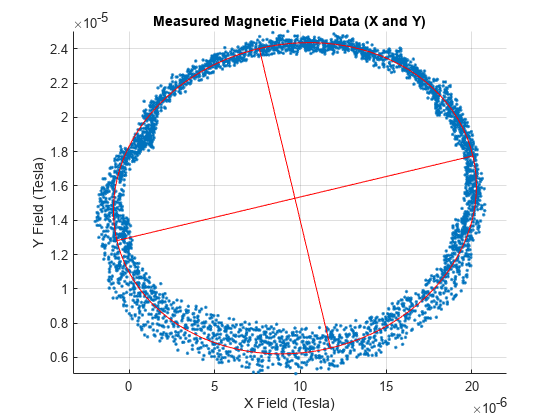

calX = calX(1225:5072); calY = calY(1225:5072); calZ = calZ(1225:5072);

figure; hold on; grid on; axis equal; scatter(calX, calY, '.'); 
xlabel('X Field (Tesla)'); ylabel('Y Field (Tesla)'); 
title('Measured Magnetic Field Data (X and Y)'); calellipse = fit_ellipse(calX, calY, gca); hold off;

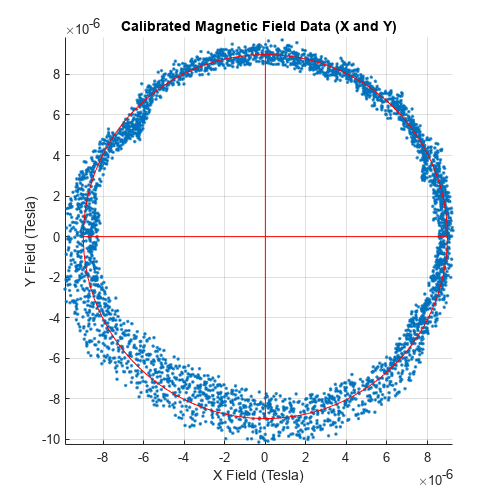


% figure(); hold on; grid on; xlabel('X Field (Tesla)'); ylabel('Y Field (Tesla)');
% title('Ellipse Fit of Measured Data'); 
% hold off;

% tan-1(y/x) is yaw

%                       a           - sub axis (radius) of the X axis of the non-tilt ellipse
%                       b           - sub axis (radius) of the Y axis of the non-tilt ellipse
%                       phi         - orientation in radians of the ellipse (tilt)
%                       X0          - center at the X axis of the non-tilt ellipse
%                       Y0          - center at the Y axis of the non-tilt ellipse
%                       X0_in       - center at the X axis of the tilted ellipse
%                       Y0_in       - center at the Y axis of the tilted ellipse
%                       long_axis   - size of the long axis of the ellipse
%                       short_axis  - size of the short axis of the ellipse
%                       status      - status of detection of an ellipse

xycenter = [calellipse.X0_in; calellipse.Y0_in];
theta = abs(calellipse.phi);
Rz = [cos(theta), -sin(theta);
      sin(theta), cos(theta)];
Sx = [(calellipse.short_axis/calellipse.long_axis) 0; 0 1];

magxy = zeros(2, length(calX));

for i = 1:length(calX)
    cals = [calX(i); calY(i)];
    magxy(:, i) = Sx*(Rz\(cals - xycenter));
end

magxy = transpose(magxy);

figure; hold on; grid on; set(gcf, 'position', [0, 0, 500, 500]);
scatter(magxy(:,1), magxy(:,2), '.'); axis equal; set(gca,'DataAspectRatio',[1 1 1]); 
xlabel('X Field (Tesla)'); ylabel('Y Field (Tesla)'); title('Calibrated Magnetic Field Data (X and Y)'); 
ellipse2 = fit_ellipse(magxy(:,1), magxy(:,2), gca); 
hold off;


% figure; hold on; grid on; set(gcf, 'position', [0, 0, 500, 500]);
% ellipse2 = fit_ellipse(magxy(:,1), magxy(:,2), gca);
% hold off;

% figure; hold on; grid on; plot(circlestime, [calX, calY, calZ]); xlabel('Time (s)'); ylabel('Magnetic Field (Tesla)'); 
% title('Magnetic Field vs. Time (Uncalibrated)'); legend('X', 'Y', 'Z'); hold off;
% 
% figure; hold on; grid on; plot(circlestime, [magxy(:,1), magxy(:,2), calZ]); xlabel('Time (s)'); ylabel('Magnetic Field (Tesla)'); 
% title('Magnetic Field vs. Time (Calibrated)'); legend('X', 'Y', 'Z'); hold off;

Sensor Fusion

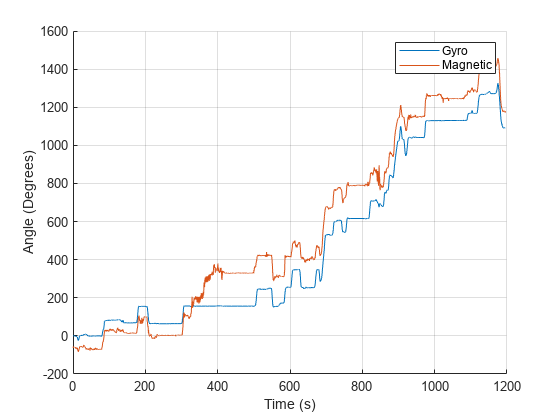

t1 = drivetime;

[difference, index] = min(abs(t1-684.773)); % remove a problematic value from the dataset
t1(index) = []; driveMagX(index) = []; driveMagY(index) = []; qX(index) = []; qY(index) = []; qZ(index) = []; qW(index) = []; driveGyroZ(index) = [];
driveGyroX(index) = []; driveGyroY(index) = []; driveAccelX(index) = []; driveAccelY(index) = []; driveAccelZ(index) = [];


L = length(t1);
eulers = zeros(L, 3);
driveMagXCal = zeros(L, 1);
driveMagYCal = zeros(L, 1);
magYaw = zeros(L, 1);
magYawCal = zeros(L, 1);

for i = 1:length(driveMagX)
    quat1 = [qW(i), qX(i), qY(i), qZ(i)];
    eulers(i,:) = rad2deg((quat2eul(quat1)));

    cals = [driveMagX(i); driveMagY(i)];
    mags = Sx*(Rz\(cals - xycenter));
    driveMagXCal(i) = mags(1);
    driveMagYCal(i) = mags(2);

    magYaw(i) = -1*(rad2deg(atan2(cals(2),cals(1))) + 8.39 + 90);
    magYawCal(i) = -1*(rad2deg(atan2(mags(2),mags(1))) + 8.39 + 90);
end

gyroYaw = rad2deg((1/40)*cumtrapz(driveGyroZ));
magYawCalFilt = unwrap(lowpass(magYawCal, .01, 40));
gyroYawFilt = highpass(gyroYaw, .05, 40);
gyroYawFilt(47560:length(gyroYawFilt)) = 0;

% figure; set(gcf, 'position', [0 0 1600 2400]); hold on;
% subplot(2,1,1); grid on; plot(t1, [driveMagX, driveMagY]); title('Mag. XY vs. Time (Uncalibrated)');
% subplot(2,1,2); grid on; plot(t1, [driveMagXCal, driveMagYCal]); title('Mag. XY vs. Time (Calibrated)'); set(gcf,'Visible','on'); hold off

% figure; hold on; grid on; plot(t1, driveGyroZ); hold off;

% figure; hold on; set(gcf, 'position', [0 0 800 480]); grid on; plot(t1, [magYaw, magYawCal]); xlabel('Time (s)'); 
% ylabel('Angle (Degrees)'); title('Magnetic Yaw vs. Time'); legend('Raw Data', 'Calibrated Data'); hold off;

figure; hold on; grid on; plot(t1, [gyroYaw, unwrap(magYawCalFilt)]); xlabel('Time (s)'); ylabel('Angle (Degrees)'); 
legend('Gyro', 'Magnetic'); hold off;

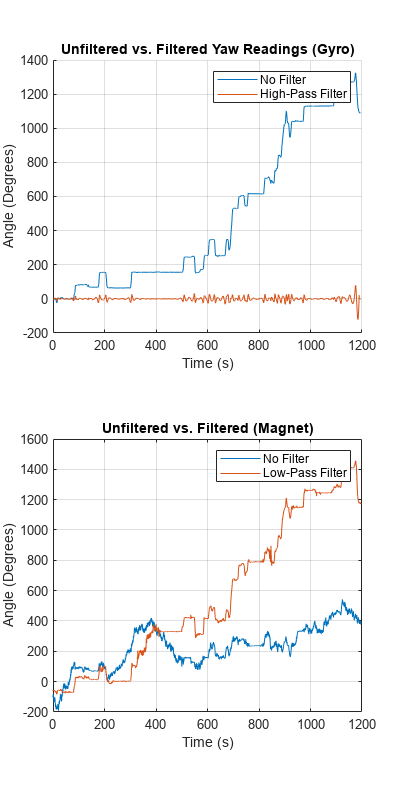


% figure; hold on; grid on; plot(t1, gyroYaw); xlabel('Time (s)'); ylabel('Angle (Degrees)'); 
% title('Integrated Gyroscope Yaw vs. Time'); hold off;

figure; subplot(2,1,1); hold on; set(gcf, 'position', [0 0 500 1000]); plot(t1, [gyroYaw, gyroYawFilt]); xlabel('Time (s)'); ylabel('Angle (Degrees)');
title('Unfiltered vs. Filtered Yaw Readings (Gyro)'); legend('No Filter', 'High-Pass Filter'); grid on;

subplot(2,1,2);plot(t1, [unwrap(magYawCal), magYawCalFilt]); xlabel('Time (s)'); ylabel('Angle (Degrees)');
title('Unfiltered vs. Filtered (Magnet)'); legend('No Filter', 'Low-Pass Filter'); grid on; hold off;

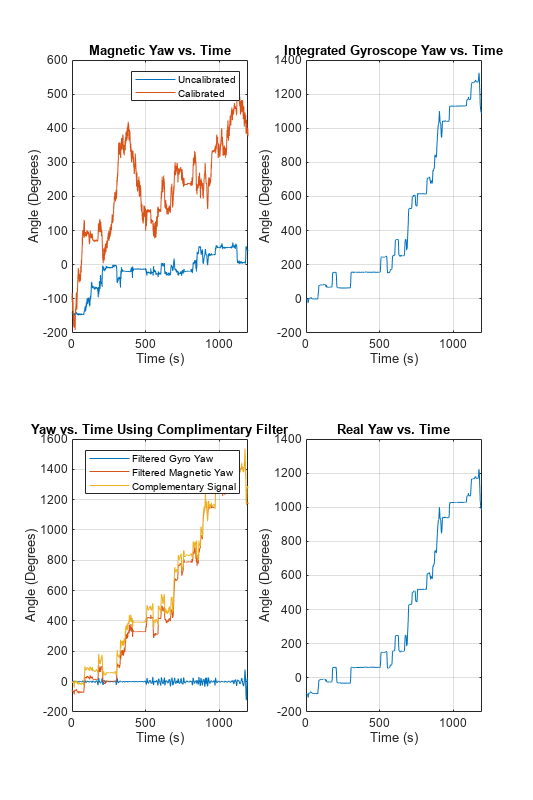


yawCF = zeros(L,1);
alpha = .5;
gyroFilts = zeros(L,1);
magFilts = zeros(L,1);

gyroYawFiltw = wrapToPi(deg2rad(gyroYaw));
magYawCalFiltw = wrapToPi(deg2rad(magYawCalFilt));


% for i = 2:L
%     theta1 = yawCF(i-1);
%     yawCF(i) = (alpha)*(theta1 + driveGyroZ(i)*.025) + (1-alpha)*deg2rad(magYawCal(i));
%     magFilts(i) = (1-alpha)*deg2rad(magYawCal(i));
%     gyroFilts(i) = (alpha)*(theta1 + driveGyroZ(i)*.025);
% end

for i = 2:L
    theta1 = yawCF(i-1);
    yawCF(i) = gyroYawFilt(i) + magYawCalFilt(i);
end

yawCF = unwrap(yawCF);

figure; hold on; set(gcf, 'position', [0 0 1600 2400]); 
subplot(2,2,1); plot(t1, [unwrap(magYaw), unwrap(magYawCal)]); xlabel('Time (s)'); ylabel('Angle (Degrees)'); 
title('Magnetic Yaw vs. Time'); legend('Uncalibrated', 'Calibrated'); grid on;  
subplot(2,2,2); plot(t1, gyroYaw); xlabel('Time (s)'); ylabel('Angle (Degrees)'); 
title('Integrated Gyroscope Yaw vs. Time'); grid on;
hold on; subplot(2,2,3); plot(t1, [gyroYawFilt, magYawCalFilt, yawCF]); xlabel('Time (s)'); ylabel('Angle (Degrees)'); 
title('Yaw vs. Time Using Complimentary Filter'); 
legend('Filtered Gyro Yaw', 'Filtered Magnetic Yaw', 'Complementary Signal'); grid on;
subplot(2,2,4); grid on; plot(t1, unwrap(eulers(:, 1))); grid on; xlabel('Time (s)'); ylabel('Angle (Degrees)'); 
title('Real Yaw vs. Time'); 
% set(gcf,'Visible','on'); 
grid on; hold off;


% figure; hold on; grid on; plot(t1, yawCF); xlabel('Time (s)'); ylabel('Angle (Degrees)'); 
% title('CF'); hold off;

Estimate Forward Velocity

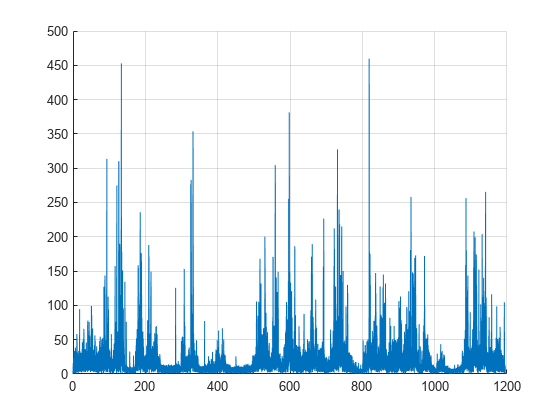

t2 = drivetime;
tGPS = GPStime;

driveVX = cumtrapz(driveAccelX);
driveVY = cumtrapz(driveAccelY);
driveVZ = cumtrapz(driveAccelZ);

driveX = cumtrapz(driveVX);

GPSVE = zeros(length(GPStime), 1);
GPSVN = zeros(length(GPStime), 1);
GPSV = zeros(length(GPStime), 1);

VZ_theory = zeros(length(GPStime), 1);

for i = 2:length(GPStime)
    prev_vals = [driveUTME(i-1); driveUTMN(i-1)];
    cur_vals = [driveUTME(i); driveUTMN(i)];
    vels = (1/(tGPS(i) - tGPS(i-1)))*(cur_vals-prev_vals);

    GPSVE(i) = vels(1);
    GPSVN(i) = vels(2);
    GPSV(i) = hypot(vels(1), vels(2));
end

%     alpha = deg2rad(eulers(i,3));
%     beta = deg2rad(eulers(i,2));
%     gamma = deg2rad(eulers(i,1));
%     Rx = [1 0 0;
%           0 cos(alpha) -sin(alpha);
%           0 sin(alpha) cos(alpha)];
%     Ry = [cos(beta) 0 sin(beta);
%           0 1 0;
%           -sin(beta) 0 cos(beta)];
%     Rz = [cos(gamma) -sin(gamma) 0;
%           sin(gamma) cos(gamma) 0;
%           0 0 1];

AX_C = driveAccelX;
AY_C = driveAccelY;
AZ_C = driveAccelZ;
% driveAccelYCor = transpose(accl_c(2,:));
% driveAccelZCor = transpose(accl_c(3,:));

h = 1/40;
jX(2:47808,1) = diff(AX_C)/h;
jY(2:47808,1) = diff(AY_C)/h;
jZ(2:47808,1) = diff(AZ_C)/h;
jM = zeros(47808,1);

for i = 1:length(jX)
    jM(i) = sqrt(jX(i)^2 + jY(i)^2 + jZ(i)^2);
end

% figure; hold on; grid on; plot(t1, [jX, jY, jZ]); legend('X', 'Y', 'Z'); hold off;
figure; hold on; grid on; plot(t1, jM); hold off;

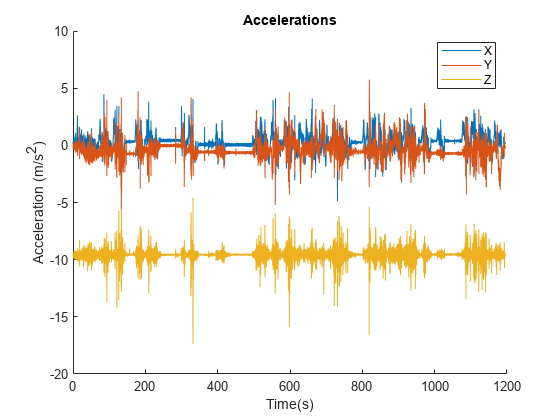


figure; hold on; plot(t1, [AX_C, AY_C, AZ_C]); legend('X', 'Y', 'Z'); title('Accelerations');
xlabel('Time(s)'); ylabel('Acceleration (m/s^2)'); hold off

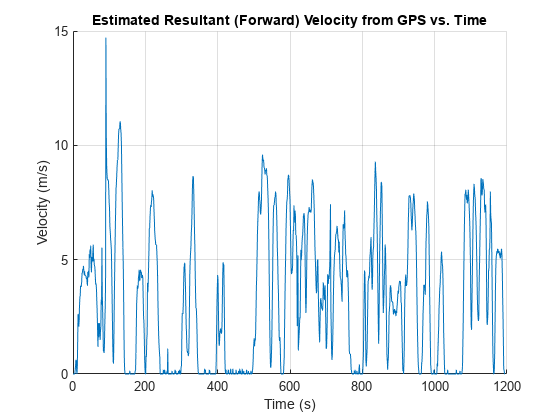


% At = (abs(AX_C) + abs(AY_C) + abs(AZ_C));

% figure; hold on; plot(t1, (abs(AX_C) + abs(AY_C) + abs(AZ_C))); hold off;

figure; hold on; plot(tGPS, GPSV); xlabel('Time (s)'); ylabel('Velocity (m/s)'); 
title('Estimated Resultant (Forward) Velocity from GPS vs. Time'); grid on; hold off;

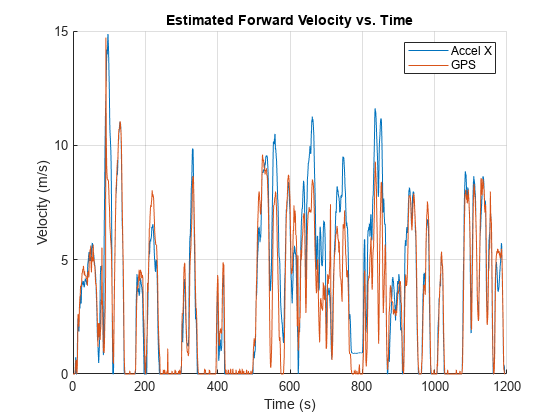


% AX_C2 = zeros(length(AX_C),1);
bias = zeros(length(AX_C),1);
bias(1:length(bias)) = mean(AX_C);
tick = zeros(length(AX_C),1);
j = 0;
m = 0;

% for i = 1:length(AX_C)
%     
% %     k = (abs(AX_C(i)) + abs(AY_C(i)) + abs(AZ_C(i)));
%     if abs(jX(i)) <= 15
%         tick(i) = 1;
%         j = j + 1;
%         m = 0;
%     else
%         tick(i) = 0;
%         m = m + 1;
%     end
%     
%     if tick(i) == 0 && m > 3 && j > 700
%         bias(i-j:length(bias)) = bias(i-j:length(bias)) + mean(AX_C2(i-j:i-4));
%         AX_C2(i-j:i-4) = AX_C2(i-j:i-4) - mean(AX_C2(i-j:i-4));
%         j = 0;
%         m = 0;
%     elseif m > 3 && j < 700
%         j = 0;
%     end
%     AX_C2(i) = AX_C(i) - bias(i);
% end

AX_C2 = AX_C - bias;
for i = 1:length(AX_C2)
    if abs(jX(i)) <= 15
        tick(i) = 1;
        j = j + 1;
        m = 0;
    else
        tick(i) = 0;
        m = m + 1;
    end
    
    if tick(i) == 0 && m > 3 && j > 700
        bias(i-j:length(bias)) = bias(i-j:length(bias)) + mean2(AX_C2(i-j:i-4));
        AX_C2(i-j:length(AX_C2)) = AX_C2(i-j:length(AX_C2)) - mean(AX_C2(i-j:i-4));
        j = 0;
        m = 0;
    elseif m > 3 && j < 700
        j = 0;
    end
end

bias_C = zeros(length(AX_C2),1);
LBC = length(bias_C);
bias_C(:) = bias_C(:) + .009534;
bias_C(6192:LBC) = bias_C(6192:LBC) + .0186264;
bias_C(6850:LBC) = bias_C(6850:LBC) - .0828447;
bias_C(8035:LBC) = bias_C(8035:LBC) + .0770397;
bias_C(7923:LBC) = bias_C(7923:LBC) + .0212113;
bias_C(9615:LBC) = bias_C(9615:LBC) - .0173177;
bias_C(8043:LBC) = bias_C(8043:LBC) + .0101321;
bias_C(11944:LBC) = bias_C(11944:LBC) - .0214651;
bias_C(13961:LBC) = bias_C(13961:LBC) + .0102526;
bias_C(15704:LBC) = bias_C(15704:LBC) - .0201765;
bias_C(20190:LBC) = bias_C(20190:LBC) + .1425777;
bias_C(23272:LBC) = bias_C(23272:LBC) - .1162843;
bias_C(19844:LBC) = bias_C(19844:LBC) - .0060326;
bias_C(28612:LBC) = bias_C(28612:LBC) + .0277495;
bias_C(30829:LBC) = bias_C(30829:LBC) - .0824365;
bias_C(32003:LBC) = bias_C(32003:LBC) - .0251420;
bias_C(34821:LBC) = bias_C(34821:LBC) - .0315066;
bias_C(36450:LBC) = bias_C(36450:LBC) + .1761456;
bias_C(38516:LBC) = bias_C(38516:LBC) - .1396111;
bias_C(39620:LBC) = bias_C(39620:LBC) + .0200331;
bias_C(40259:LBC) = bias_C(40259:LBC) - .0247310;
bias_C(41115:LBC) = bias_C(41115:LBC) + .0476582;
bias_C(43022:LBC) = bias_C(43022:LBC) - .0839448;
bias_C(46506:LBC) = bias_C(46506:LBC) - .0264091;

AX_C2 = AX_C2 - bias_C;
AX_C2(3360:4438) = AX_C2(3360:4438) * 1.95;
AX_C2(33068:34289) = AX_C2(33068:34289) * .55;
AX_C2(20793:23239) = AX_C2(20793:23239) * .8;

VFWD = (1/40)*cumtrapz(AX_C2);

for i = 1:length(VFWD)
    if VFWD(i) < .2
        VFWD(i) = 0;
    end
end

% figure; hold on; grid on; plot(t1, AX_C); hold off
% figure; hold on; grid on; plot(t1, [AX_C, AX_C2, bias]); legend('1', '2', 'bias'); hold off;
figure; hold on; plot(t1, VFWD); plot(tGPS, GPSV); legend('Accel X', 'GPS'); xlabel('Time (s)'); ylabel('Velocity (m/s)'); 
title('Estimated Forward Velocity vs. Time'); grid on; hold off;

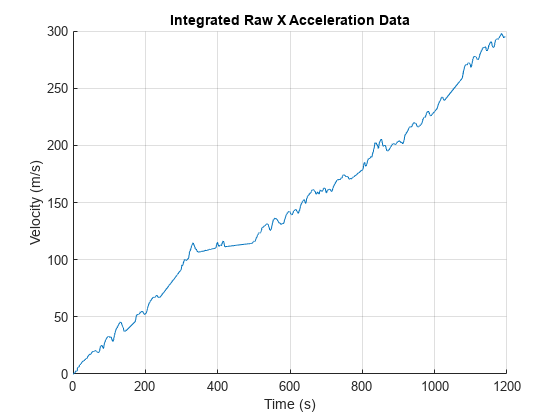

figure; hold on; plot(t1, .025*cumtrapz(AX_C)); xlabel('Time (s)'); ylabel('Velocity (m/s)'); 
title('Integrated Raw X Acceleration Data'); grid on; hold off;

Dead Reckoning

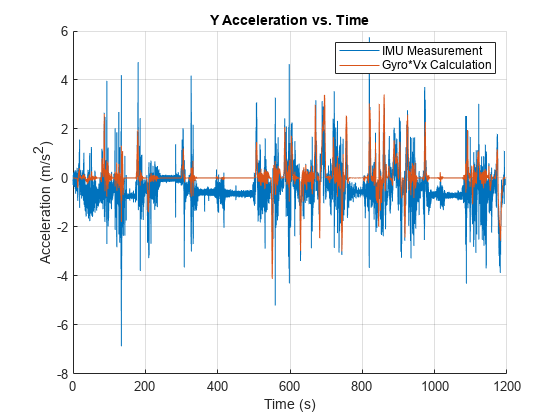

X = (1/40)*cumtrapz(VFWD);

CM = [0 0 0];
accelYCalc = zeros(L,1);

thetas = -1*wrapToPi(deg2rad(yawCF)) + pi/1.85;
thetas = -1*wrapToPi(deg2rad(gyroYaw)) + pi/1.65;

Ve = zeros(L,1);
Vn = zeros(L,1);

for i = 1:L
    accelYCalc(i) = driveGyroZ(i) * VFWD(i);
    Ve(i) = VFWD(i)*cos(thetas(i));
    Vn(i) = VFWD(i)*sin(thetas(i));
end

Xe = 1/40*cumtrapz(Ve);
Xn = 1/40*cumtrapz(Vn);

figure; hold on; plot(t1, [driveAccelY, accelYCalc]); xlabel('Time (s)'); 
ylabel('Acceleration (m/s^2)'); legend('IMU Measurement', 'Gyro*Vx Calculation'); 
title('Y Acceleration vs. Time'); grid on; hold off;

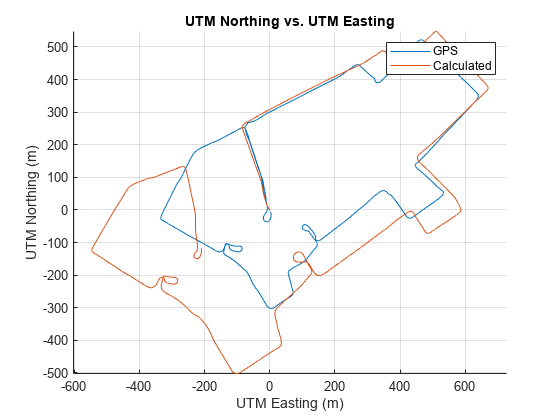


figure; hold on; plot(driveUTME-driveUTME(1), driveUTMN-driveUTMN(1)); plot(Xe, Xn); xlabel('UTM Easting (m)'); 
ylabel('UTM Northing (m)'); legend('GPS', 'Calculated'); 
title('UTM Northing vs. UTM Easting'); grid on; axis equal; hold off;



% x = vcostheta
% y = vsintheta